## **Proudění plynů a par - Zužující se dýza**

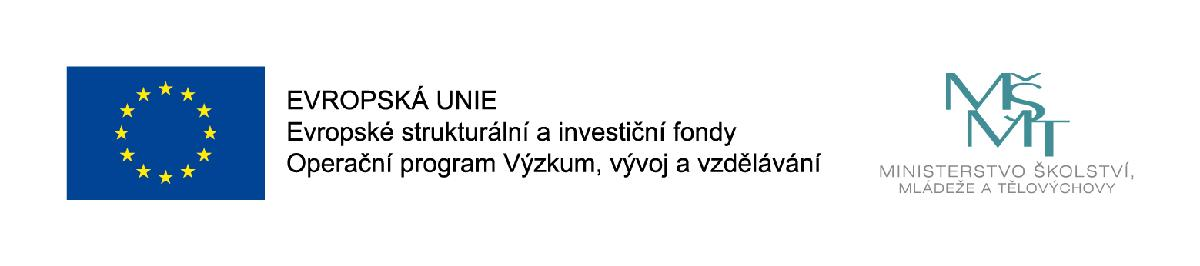

#### prof. Ing. Josef ŠTĚTINA, Ph.D. / Vysoké učení technické v Brně

#### email: [josef.stetina@vutbr.cz](mailto:josef.stetina@vutbr.cz)

#### www: [http://termomechanika.online/](http://termomechanika.online/)

#### www: [http://bit.ly/termomechanika_online/](http://bit.ly/termomechanika_online/)

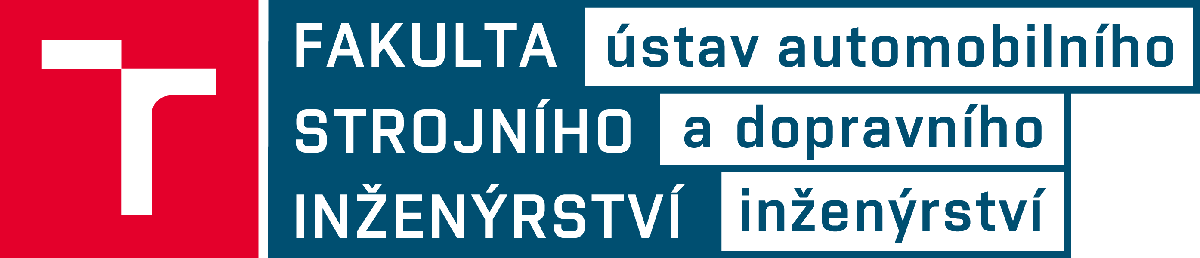

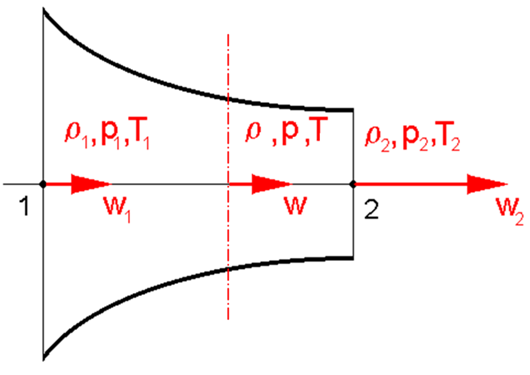


$$d{a_t} =  - dh = d\frac{{{w^2}}}{2}$$



$${h_1} - h = \frac{{{w^2} - w_1^2}}{2}\quad  \Rightarrow \quad w = \sqrt {2({h_1} - h) + w_1^2} $$



$$w  = \sqrt {2({h_1} - h)} = \sqrt {2{a_t}}  = \sqrt {\frac{{2\kappa }}{{\kappa  - 1}} {p_1}{v_1}\left[ {1 - {{\left( {\frac{p}{{{p_1}}}} \right)}^{\frac{{\kappa  - 1}}{\kappa }}}} \right]}$$



$$$\dot m = \frac{S}{v}\sqrt {\frac{{2\kappa }}{{\kappa  - 1}}{p_1}{v_1}\left[ {1 - {{\left( {\frac{p}{{{p_1}}}} \right)}^{\frac{{\kappa  - 1}}{\kappa }}}} \right]} $$$



$$$v = {v_1}{\left( {\frac{{{p_1}}}{p}} \right)^{\frac{1}{\kappa }}}$$$



$$$\dot m = \frac{S}{{{v_1}}}{\left( {\frac{p}{{{p_1}}}} \right)^{\frac{1}{\kappa }}}\sqrt {\frac{{2\kappa }}{{\kappa  - 1}}{p_1} \cdot {v_1}\left[ {1 - {{\left( {\frac{p}{{{p_1}}}} \right)}^{\frac{{\kappa  - 1}}{\kappa }}}} \right]}  = S \cdot \Psi \sqrt {2\frac{{{p_1}}}{{{v_1}}}} $$$



$$\[\Psi  = \sqrt {\frac{\kappa }{{\kappa  - {1_{}}}}} \sqrt {{{\left( {\frac{p}{{{p_1}}}} \right)}^{\frac{2}{\kappa }}} - {{\left( {\frac{p}{{{p_1}}}} \right)}^{\frac{{\kappa  + 1}}{\kappa }}}}  = \sqrt {\frac{\kappa }{{\kappa  - {1_{}}}}} \sqrt {{{\left( \beta  \right)}^{\frac{2}{\kappa }}} - {{\left( \beta  \right)}^{\frac{{\kappa  + 1}}{\kappa }}}} \]$$



$$\[\beta  = \;\frac{p}{{{p_1}}}\]$$



$$$\Psi  = f\;\left( {\kappa ,\;\frac{p}{{{p_1}}}} \right)$$$



$$\[{\beta _K} = \frac{{{p_K}}}{{{p_1}}} = {\left( {\frac{2}{{\kappa  + 1}}} \right)^{\frac{\kappa }{{\kappa  - 1}}}}\]$$


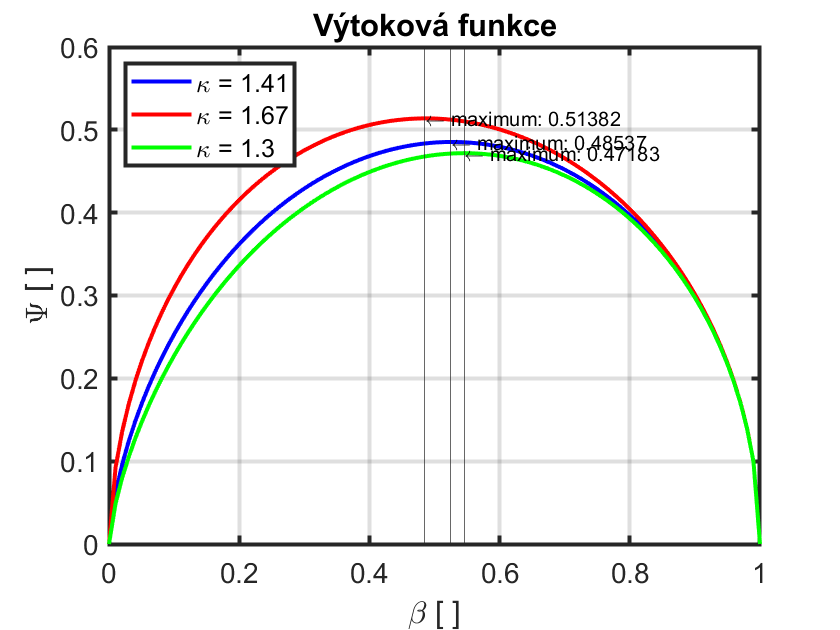

beta = linspace(0,1,100);
kappa = 1.41;
psi_1 = sqrt(kappa/(kappa-1))*sqrt(beta.^(2/kappa)-beta.^((kappa+1)/kappa));
kappa = 1.67;
psi_2 = sqrt(kappa/(kappa-1))*sqrt(beta.^(2/kappa)-beta.^((kappa+1)/kappa));
kappa = 1.3;
psi_3 = sqrt(kappa/(kappa-1))*sqrt(beta.^(2/kappa)-beta.^((kappa+1)/kappa));
figure
plot(beta,psi_1,'-b','linewidth',2);
hold on;
plot(beta,psi_2,'-r','linewidth',2);
plot(beta,psi_3,'-g','linewidth',2);
hold off;
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
title('Výtoková funkce') 
xlabel('\beta [ ]') 
ylabel('\Psi [ ]') 
grid on;
[p1, ib1] = max(psi_1); 
txt = ['\leftarrow maximum: ' num2str(p1) ]; 
text(beta(ib1),p1,txt) 
xline(beta(ib1))
[p1, ib1] = max(psi_2); 
txt = ['\leftarrow maximum: ' num2str(p1) ]; 
text(beta(ib1),p1,txt) 
xline(beta(ib1))
[p1, ib1] = max(psi_3); 
txt = ['\leftarrow maximum: ' num2str(p1) ]; 
text(beta(ib1),p1,txt) 
xline(beta(ib1))
legend({'\kappa = 1.41','\kappa = 1.67','\kappa = 1.3'},'Location','northwest') 

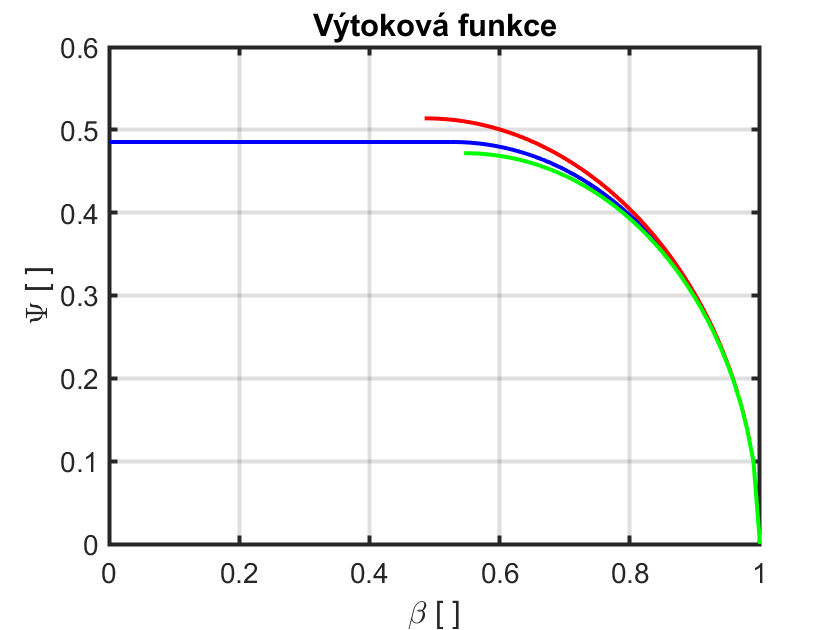

beta = linspace(0,1,100);
kappa = 1.41;
psi_1 = sqrt(kappa/(kappa-1))*sqrt(beta.^(2/kappa)-beta.^((kappa+1)/kappa));
kappa = 1.67;
psi_2 = sqrt(kappa/(kappa-1))*sqrt(beta.^(2/kappa)-beta.^((kappa+1)/kappa));
kappa = 1.3;
psi_3 = sqrt(kappa/(kappa-1))*sqrt(beta.^(2/kappa)-beta.^((kappa+1)/kappa));
figure
[p1, ib1] = max(psi_1);
plot(beta(ib1:end),psi_1(ib1:end),'-b','linewidth',2);
hold on;
[p2, ib2] = max(psi_2);
bb(1) = 0;
bb(2) = beta(ib1);
pp(1) = psi_1(ib1);
pp(2) = psi_1(ib1);
plot(bb,pp,'-b','linewidth',2);

plot(beta(ib2:end),psi_2(ib2:end),'-r','linewidth',2);
[p3, ib3] = max(psi_3);
plot(beta(ib3:end),psi_3(ib3:end),'-g','linewidth',2);
hold off;
set(gca, 'fontsize', 14,'linewidth',2);
ax1 = gca;
axis([ax1],[0 1 0 0.6])
title('Výtoková funkce') 
xlabel('\beta [ ]') 
ylabel('\Psi [ ]') 
grid on;